x_axis = linspace(0,50,length(EDA_Pilot_Interval_Trial_6));
 

y = EDA_Pilot_Interval_Trial_6(:,2);

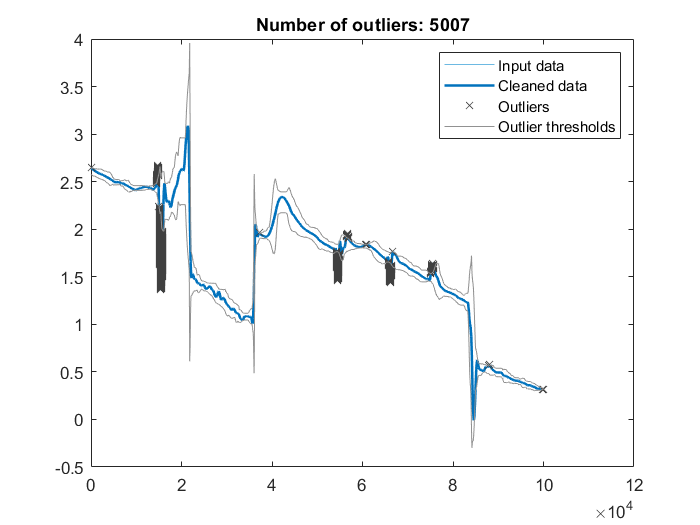

% Remove outliers
[cleanedData2,outlierIndices2] = rmoutliers(y,'movmedian',4000,...
    'ThresholdFactor',1.5);

% Display results
clf
plot(y,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(find(~outlierIndices2),cleanedData2,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Cleaned data')

% Plot outliers
plot(find(outlierIndices2),y(outlierIndices2),'x','Color',[64 64 64]/255,...
    'DisplayName','Outliers')
title(['Number of outliers: ' num2str(nnz(outlierIndices2))])

% Compute thresholds and center
[~,thresholdLow,thresholdHigh] = isoutlier(y,'movmedian',4000,...
    'ThresholdFactor',1.5);

% Plot outlier thresholds
plot([(1:numel(y))'; missing; (1:numel(y))'],...
    [thresholdHigh(:); missing; thresholdLow(:)],'Color',[145 145 145]/255,...
    'DisplayName','Outlier thresholds')

hold off
legend

clear thresholdLow thresholdHigh

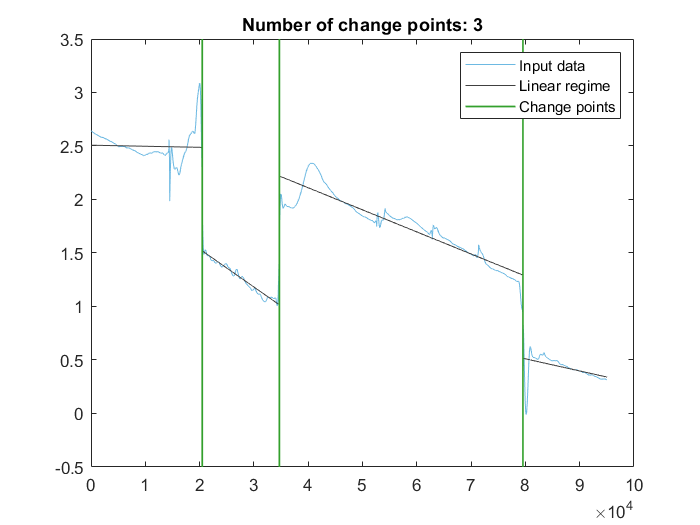

% Find change points
[changeIndices,segmentSlope,segmentIntercept] = ischange(cleanedData2,'linear',...
    'Threshold',500);

% Display results
clf
plot(cleanedData2,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on

% Plot segments between change points
plot(segmentSlope(:).*(1:numel(cleanedData2))'+segmentIntercept(:),...
    'Color',[64 64 64]/255,'DisplayName','Linear regime')

% Plot change points
x = repelem(find(changeIndices),3);
y2 = repmat([ylim(gca) NaN]',nnz(changeIndices),1);
plot(x,y2,'Color',[51 160 44]/255,'LineWidth',1,'DisplayName','Change points')
title(['Number of change points: ' num2str(nnz(changeIndices))])

hold off
legend

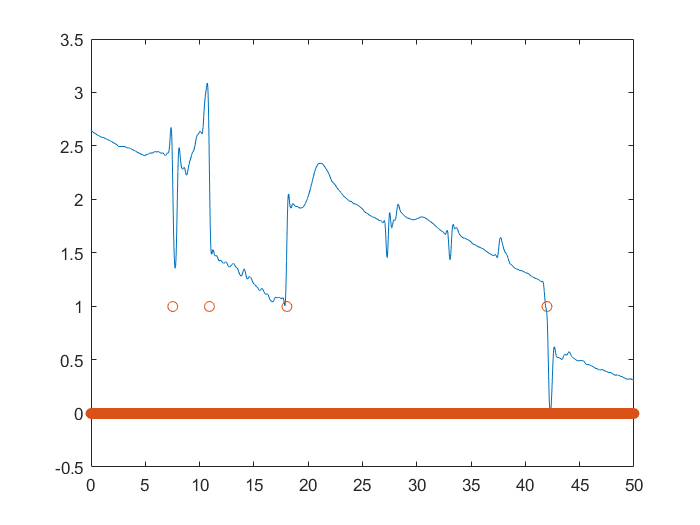

clear segmentSlope segmentIntercept x y2


plot(x_axis,y);
hold on;
[tf,s1] = ischange(y,'linear','Threshold',500);

plot(x_axis,tf,'o');

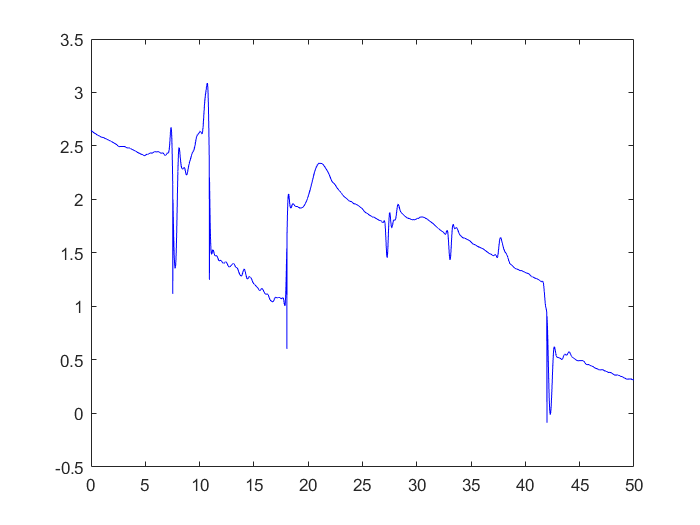



figure;
plot(x_axis, y-tf,'-b');